Set up environment necessary for plots

load('LIMO_output_Tap/clustering_output.mat', 'mask', 'cluster_p', 'one_sample');
load('LIMO_output_Tap/ALL_LIMO_INFO.mat', 'LIMOs');

load('LIMO_output_FS_event/inter_tap_intervals.mat', "inter_tap_intervals")

inter_tap_intervals_FS = inter_tap_intervals;
clear inter_tap_intervals;

load('LIMO_output_Tap/inter_tap_intervals.mat', "inter_tap_intervals")
load('MATLAB\expected_chanlocs.mat');


avg_activation_FS = load('LIMO_output_FS_event/avg_activation.mat').avg_activation;
avg_activation_Tap = load('LIMO_output_Tap/avg_activation.mat').avg_activation;


event_names = {'FS_event', 'Tap'};
epoch_size = [-3, 0.5]; % In seconds
electrodes = [1, 2, 6, 10, 16]; % Which electrodes to show for electrode-specific plots

inter_tap_intervals = inter_tap_intervals(mod(1:size(inter_tap_intervals, 2), 2) ~= 0);
inter_tap_intervals_FS = inter_tap_intervals_FS(mod(1:size(inter_tap_intervals_FS, 2), 2) ~= 0);
latencies = cellfun(@(x) iti2latency(x), inter_tap_intervals, 'UniformOutput', false);

betas = extract_betas(LIMOs);
betas_names = {'k_{t-1}', 'k_{t+1}', 'Bias'};


% Find electrode with maximum mean smartphone tap activation
mean_activation = trimmean(avg_activation_Tap, 20, 3);

figure_font = 'Helvetica';
    
maximum_values = max(abs(mean_activation), [], 2);
[~, maximum_electrode] = max(maximum_values);

electrodes = maximum_electrode;

clear LIMOs;

## Figure 1

Joint inter-tap-interval distributions

nbinsJID = 50;
edge_alpha = 0.05;

nBinsHistogram = 30;

f = figure;
f.Units = "inches";
f.Position = [ 3.7, 9.3, 9, 3.4 ];

f = set_figure_fonts(f, figure_font);


sgtitle({'Inter-tap-interval distribution', ''});

tiledlayout(1, 3, "TileSpacing", "normal", "Padding", "normal");

% Histogram of ITIs
%nexttile;
%title({'', 'Inter-tap interval distribution', ''});
%hold on;
%cellfun(@(x) histogram(x(x < 10000), nBinsHistogram), inter_tap_intervals, 'UniformOutput', false);
%hold off;

%xlabel("ITI");
%ylabel("Count");

%%% TODO: Replace histogram with density plot
nexttile;

counts_all = [inter_tap_intervals{:}];

fit_2 = fitdist(counts_all(counts_all < 10000)', 'Kernel');
x_values = 0:10000;
y = pdf(fit_2,x_values);
yyaxis left;
plot(x_values, y , '-b');

hold on;

% Cumulative distribution
cum_distribution_tap = cdf(fit_2,x_values);
yyaxis right;
plot(x_values,cum_distribution_tap, '--b');


% hist_fit = histfit(counts_all(counts_all < 10000), nBinsHistogram, 'kernel');
% hist_fit(1).FaceColor = [.8, .8, 1];
% hist_fit(1).EdgeColor = [.6, .6, .8];
% hist_fit(1).FaceAlpha = 0.3;
% hist_fit(2).Color = hex2color('04EB90');




counts_all = [inter_tap_intervals_FS{:}];

fit_2 = fitdist(counts_all(counts_all < 10000)', 'Kernel');
x_values = 0:10000;
y = pdf(fit_2,x_values);
yyaxis left;
plot(x_values, y, '-r');

cum_distribution_FS = cdf(fit_2,x_values);
yyaxis right;
plot(x_values,cum_distribution_FS, '--r');

%hist_fit = histfit(counts_all(counts_all < 10000), nBinsHistogram, 'kernel');
% hist_fit(1).FaceColor = [.8, .8, 1];
% hist_fit(1).EdgeColor = [.6, .6, .8];
% hist_fit(1).FaceAlpha = 0.3;
% hist_fit(2).Color = hex2color('FA002E');

%h = findobj(gca,'Type','line');
h = legend({'Phone density', 'FS density', 'Phone cumulative', 'FS cumulative'}, 'Location',"southoutside");


title({'', 'Inter-tap interval distribution', ''});
xlabel("ITI ms");

xlim([0, 10000]);
xticks(0:2500:10000);

yyaxis left;
ylabel("Density");

yyaxis right;
ylabel("Cumulative Probability");
ylim([0 1]);

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';



set(gca, 'TickDir', 'out');


## JID Plots

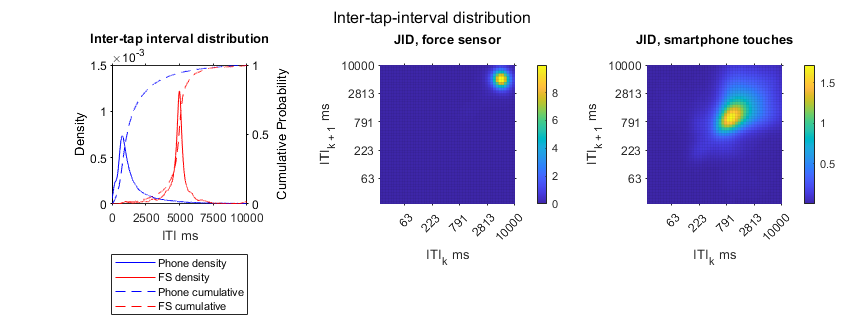

% Single JID plot
%[jid_single, binEdges] = PlottingFunctions.taps2JID(iti2latency(inter_tap_intervals{1}')', 'Bins', nbinsJID);

MINH = log10(20);
MAXH = log10(10000);

nexttile;

jid_multi = zeros(nbinsJID, nbinsJID, size(betas, 4));



for ppt = 1:size(jid_multi, 3)
    [jid_multi(:, :, ppt), binEdges] = PlottingFunctions.taps2JID(iti2latency(inter_tap_intervals_FS{ppt}')', 'Bins', nbinsJID, 'MINH', MINH, 'MAXH', MAXH);
end

jid_average = mean(jid_multi, 3);


jid_plot_avg = pcolor(jid_average);
jid_plot_avg.EdgeAlpha = edge_alpha;
title({'', 'JID, force sensor', ''}, 'FontName', 'Arial');
colorbar();

xlabel("ITI_{k} ms");
ylabel("ITI_{k + 1} ms");

xtick_values = xticks();
xticklabels(round(binEdges(round(xtick_values))));
xtickangle(45);

ytick_values = yticks();
yticklabels(round(binEdges(round(ytick_values))));

set(gca, 'TickDir', 'out');

% Average JID plot
jid_multi = zeros(nbinsJID, nbinsJID, size(betas, 4));

for ppt = 1:size(jid_multi, 3)
    [jid_multi(:, :, ppt), binEdges] = PlottingFunctions.taps2JID(iti2latency(inter_tap_intervals{ppt}')', 'Bins', nbinsJID, 'MINH', MINH, 'MAXH', MAXH);
end

jid_average = mean(jid_multi, 3);

nexttile;

jid_plot_avg = pcolor(jid_average);
jid_plot_avg.EdgeAlpha = edge_alpha;
title({'', 'JID, smartphone touches', ''}, 'FontName', 'Arial');
colorbar();

xlabel("ITI_{k} ms");
ylabel("ITI_{k + 1} ms");

xtick_values = xticks();
xticklabels(round(binEdges(round(xtick_values))));
xtickangle(45);

ytick_values = yticks();
yticklabels(round(binEdges(round(ytick_values))));
set(gca, 'TickDir', 'out');

save_svg(f, fullfile("figures", "hist_JID"));

### Figure 2

Alternative plots, all in one

participant = 2;
time_points = -2999:500;

xlims = [-3000, 500];
xticks_values = [-3000, -2000, -1000, -500, 0, 500];

smooth_size = 45;
top_percentile = 80;
bottom_percentile = 20;
fill_alpha = 0.3;

f = figure;
f = set_figure_fonts(f, figure_font);

sgtitle("Trimmed mean of epoched ERP signal and 95% confidence interval");

f.Units = "inches";
f.Position = [ 3.7, 9.3, 9, 3 ];
set(gca, 'FontName', 'Helvetica');
tiledlayout(1, 2);

Force sensor touch

nexttile;
hold on;
title("Force sensor touches");


mean_line = squeeze(mean(avg_activation_FS(electrodes, :, :), 3))';

[~,tm,trimci,~,~,~,~] = limo_trimci(squeeze(avg_activation_FS));
mean_line = squeeze(tm(electrodes, :));
mean_line = smoothdata(mean_line, 'gaussian', smooth_size);  

top = squeeze(trimci(electrodes, :, 2));
top = smoothdata(top, 'gaussian', smooth_size);  

% Negative Area
bottom = squeeze(trimci(electrodes, :, 1));
bottom = smoothdata(bottom, 'gaussian', smooth_size);


x = -3000:499;

h = shade.shade(x, top, x, mean_line, 'FillType', [1 2;2 1], 'FillColor', hex2color('04EB90'), 'FillAlpha', fill_alpha);
%h(1).Visible = 'off';
%h(2).Visible = 'off';

h = shade.shade(x, bottom, x, mean_line, 'FillType', [1 2;2 1], 'FillColor', hex2color('FA002E'), 'FillAlpha', fill_alpha);
%h(1).Visible = 'off';
%h(2).Visible = 'off';

%plot(time_points, squeeze(avg_activation_FS(electrodes, :, participant))');
plot(time_points, mean_line, 'LineWidth', 2, 'Color', 'black');
xlim(xlims);
xticks(xticks_values);
xline(0);
yline(0);

xlabel("Time from epoch center in ms");
ylabel("Normalized voltage");

ylims_FS = ylim;

Smartphone Touch

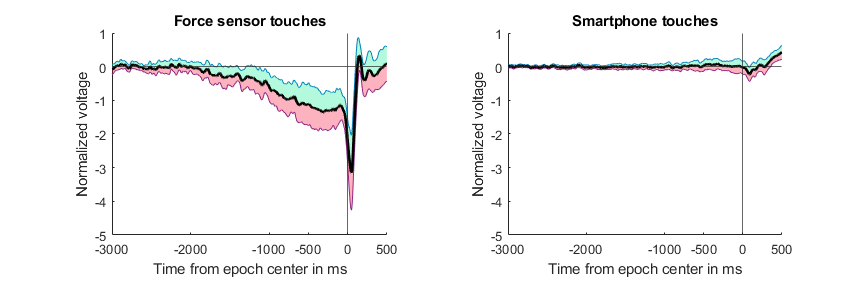


nexttile;
hold on;
title("Smartphone touches");

mean_line = squeeze(mean(avg_activation_Tap(electrodes, :, :), 3))';

[~,tm,trimci,~,~,~,~] = limo_trimci(squeeze(avg_activation_Tap));
mean_line = squeeze(tm(electrodes, :));
mean_line = smoothdata(mean_line, 'gaussian', smooth_size);  

top = squeeze(trimci(electrodes, :, 2));
top = smoothdata(top, 'gaussian', smooth_size);  

% Negative Area
bottom = squeeze(trimci(electrodes, :, 1));
bottom = smoothdata(bottom, 'gaussian', smooth_size);


x = -3000:499;

h =shade.shade(x, top, x, mean_line, 'FillType', [1 2;2 1], 'FillColor', hex2color('04EB90'), 'FillAlpha', fill_alpha);
%h(1).Visible = 'off';
%h(2).Visible = 'off';

h = shade.shade(x, bottom, x, mean_line, 'FillType', [1 2;2 1], 'FillColor', hex2color('FA002E'), 'FillAlpha', fill_alpha);
%h(1).Visible = 'off';
%h(2).Visible = 'off';

%plot(time_points, squeeze(avg_activation_Tap(electrodes, :, participant))');
plot(time_points, mean_line, 'LineWidth', 2, 'Color', 'black');


xlim(xlims);
xticks(xticks_values);
xline(0);
yline(0);

xlabel("Time from epoch center in ms");
ylabel("Normalized voltage");

ylim(ylims_FS)

%legend(["Single participant", "Averaged"], 'location', 'southhwest'); 
% h = findobj(gca,'Type', 'patch');
% h = flipud(h);
% legend(h, { ...
%     "95% CI Upper Bound", ...
%     "95% CI Lower Bound"}, ...
%     'Location',"southwest");

save_svg(f, fullfile("figures", "ERP_plots_2tiled"));

Extra little figure for electrode location

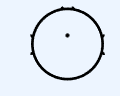

f = figure;
f = set_figure_fonts(f, figure_font);

f.Units = "inches";
f.Position = [ 1, 1, 1, 1 ];

topoplot(zeros(64, 1), expected_chanlocs, 'style', 'blank', 'plotchans', electrodes);

save_svg(f, fullfile("figures", "electrode_position"));

### Topoplots of activation

Topoplots of FS  and smartphone touch activation over time

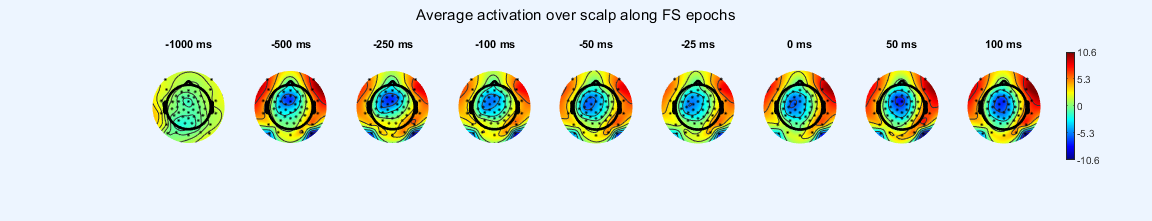

% Setup

data_size = size(avg_activation_FS);
epoch_center = 3000;

which_ppt = 1;

sample_times = [2000, 2500, 2750, 2900, 2950, 2975, 3000, 3050, 3100];
sample_times_text = sample_times - epoch_center;


% FS topo
f = figure;
f = set_figure_fonts(f, figure_font);
f.Units = "inches";
f.Position = [ 3.7, 9.3, 12, 2.3 ];

sgtitle("Average activation over scalp along FS epochs");
tiledlayout(1, 9);
nexttile;

sampled_data = squeeze(avg_activation_FS(:, sample_times, which_ppt));

max_abs_activation_value = max(abs(sampled_data), [], 'all');
heatmap = [-max_abs_activation_value, max_abs_activation_value];

for time_slice = 1:size(sampled_data, 2)
    subplot(1, size(sampled_data, 2), time_slice);
    title({'', sprintf("%d ms", sample_times_text(time_slice)), ''});
    topoplot(sampled_data(:, time_slice), expected_chanlocs, 'maplimits', heatmap);
end

% Heatmap legend
c = cbar('vert', 0, heatmap);
c.Position(3) = c.Position(3) * 3;
c.Position(2) = c.Position(1) - (c.Position(1) * 0.7);
c.Position(4) = c.Position(4) * 0.6;

save_svg(f, fullfile("figures", "ERP_topoplot_FS"));

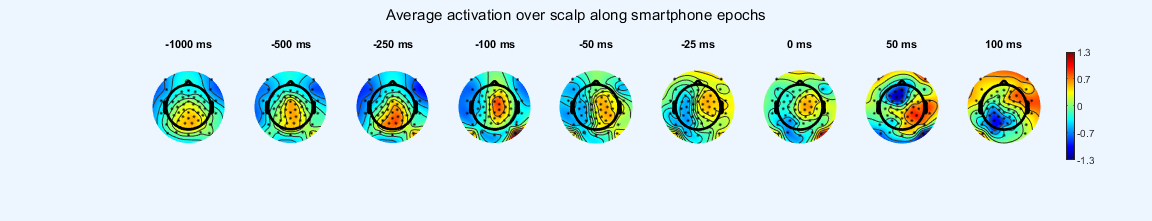


% Smartphone tap topo
f = figure;
f.Units = "inches";
f.Position = [ 3.7, 9.3, 12, 2.3 ];

sgtitle("Average activation over scalp along smartphone epochs");

sampled_data = squeeze(avg_activation_Tap(:, sample_times, which_ppt));
heatmap = [min(sampled_data, [], 'all'), max(sampled_data, [], 'all')];

for time_slice = 1:size(sampled_data, 2)
    subplot(1, size(sampled_data, 2), time_slice);
    title({'', sprintf("%d ms", sample_times_text(time_slice)), ''});
    topoplot(sampled_data(:, time_slice), expected_chanlocs, 'maplimits', heatmap);
end

c = cbar('vert', 0, heatmap);
c.Position(3) = c.Position(3) * 3;
c.Position(2) = c.Position(1) - (c.Position(1) * 0.7);
c.Position(4) = c.Position(4) * 0.6;

save_svg(f, fullfile("figures", "ERP_topoplot_Smartphone"));


clear cum_distribution*

### Figure 3

### Beta plots

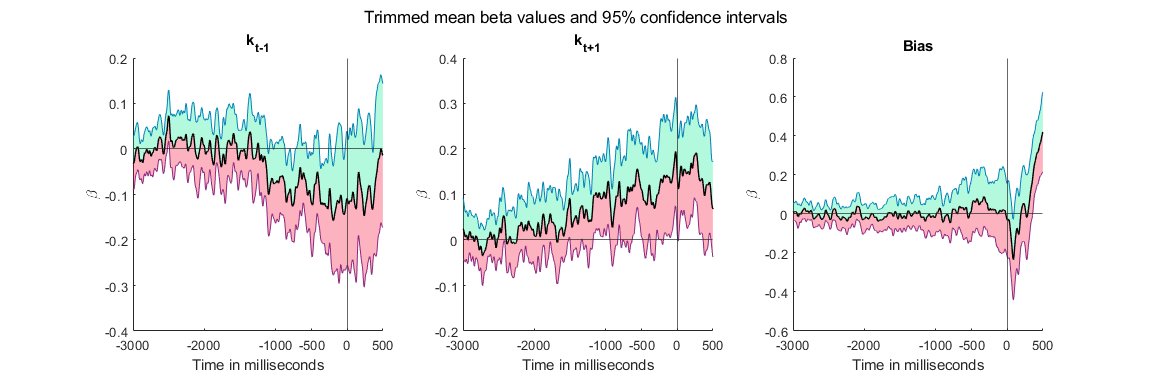

titles = ["k_t-1", "k_t+1", "Bias"];
xticks_values = [-3000, -2000, -1000, -500, 0, 500];

use_trimmed_mean = true;

f = figure;
f = set_figure_fonts(f, figure_font);
f.Units = "inches";
f.Position = [ 3.7, 9.3, 12, 4 ];

sgtitle("Trimmed mean beta values and 95% confidence intervals");    
tiledlayout(1, 3);

for beta = 1:size(betas, 3)
    nexttile;
    hold on;
    
    % Calculate mean line
    if use_trimmed_mean
        electrode_values = squeeze(betas(electrodes, :, beta, :));
        electrode_values = sort(electrode_values, 2);
        mean_indices = floor(size(electrode_values, 2) * 0.1):ceil(size(electrode_values, 2) * 0.9);
        mean_line = mean(electrode_values(:, mean_indices), 2);
    else
        mean_line = mean(squeeze(betas(electrodes, :, beta, :)), 2);
    end
    
    
    
    
    % Add area    
    % Positive Area
    
    %top = prctile(squeeze(betas(maximum_electrode, :, beta, :)), top_percentile, 2);
    %top = smoothdata(top, 'gaussian', smooth_size);  
    
    [~,tm,trimci,~,~,~,~] = limo_trimci(squeeze(betas(:, :, beta, :)));
    
    mean_line = squeeze(tm(electrodes, :));
    mean_line = smoothdata(mean_line, 'gaussian', smooth_size);  
    
    top = squeeze(trimci(electrodes, :, 2));
    top = smoothdata(top, 'gaussian', smooth_size);  
    

    % Negative Area
    %bottom = prctile(squeeze(betas(maximum_electrode, :, beta, :)), bottom_percentile, 2);
    %bottom = smoothdata(bottom, 'gaussian', smooth_size); 
    
    bottom = squeeze(trimci(electrodes, :, 1));
    bottom = smoothdata(bottom, 'gaussian', smooth_size);
    
    x = -3000:499;
    
    h = shade.shade(x, top, x, mean_line, 'FillType', [1 2;2 1], 'FillColor', hex2color('04EB90'), 'FillAlpha', fill_alpha);
    %h(1).Visible = 'off';
    %h(2).Visible = 'off';
    
    h = shade.shade(x, bottom, x, mean_line, 'FillType', [1 2;2 1], 'FillColor', hex2color('FA002E'), 'FillAlpha', fill_alpha);
    %h(1).Visible = 'off';
    %h(2).Visible = 'off';
    
    
    plot_beta_mean = plot(epoch_size(1) * 1000 + 1:epoch_size(2) * 1000, mean_line, 'LineWidth', 1, 'color', [0, 0, 0]);
    
    
    t = title(["", betas_names{beta}]);
    %t.Position = [ t.Position(1), -2.5, t.Position(3) ];
    
    xline(0);
    yline(0);
    xlim(epoch_size * 1000);
    xticks(xticks_values);
    
    xlabel("Time in milliseconds");
    ylabel("\beta");
end

% h = findobj(gca,'Type', 'patch');
% h = flipud(h);
% legend(h, { ...
%     "95% CI Upper Bound", ...
%     "95% CI Lower Bound"}, ...
%     'Location',"northwest");


save_svg(f, fullfile("figures", "beta_plot"))

### Topoplot of thresholded t-values

Averaged across participants

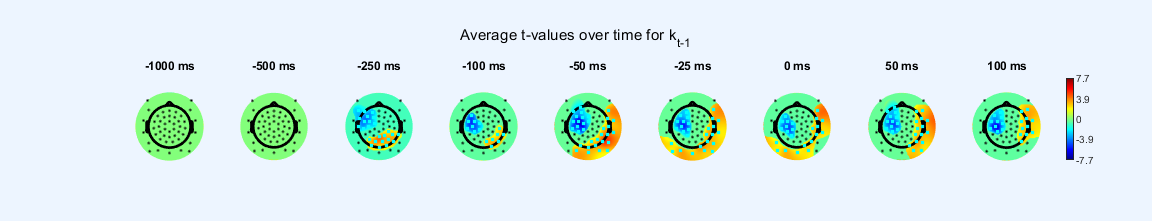

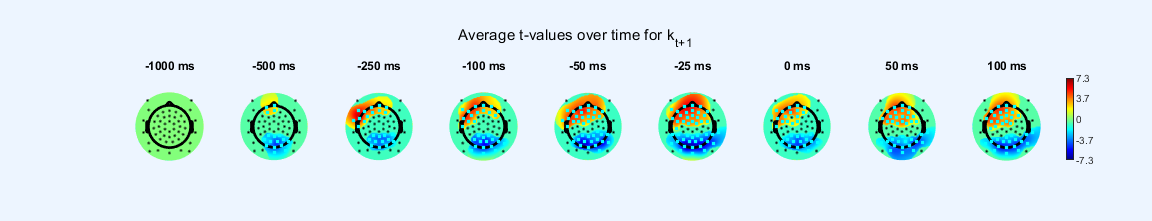

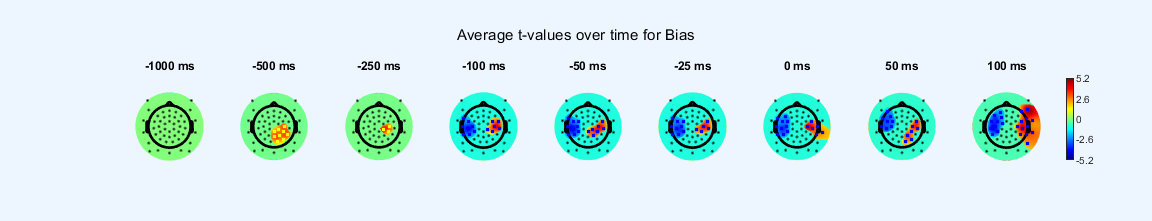

titles = ["k_t-1", "k_t+1", "Bias"];

for beta = 1:size(one_sample, 4)
    % Smartphone tap topo
    f = figure;
    f = set_figure_fonts(f, figure_font);
    f.Units = 'inches';
    f.Position = [ 3.7, 9.3, 12, 2.3 ];
    
    sgtitle({"", sprintf("Average t-values over time for %s", betas_names{beta}), ""});
    tiledlayout(f, 1, 9, 'TileSpacing', 'compact');
    
    sampled_data = squeeze(one_sample(:, sample_times, 4, beta));
    
    
    
    % Get heatmap
    max_abs_beta_value = max(abs(sampled_data), [], 'all');
    
    heatmap = [-max_abs_beta_value, max_abs_beta_value];
    
    clusters = unique(squeeze(mask(:, sample_times, beta)));
    n_clusters = length(clusters) - 1;
    clusterColors = [0, 0, 0; jet(max(clusters))];
    
    for time_slice = 1:size(sampled_data, 2)
        nexttile;
        title({'', sprintf("%d ms", sample_times_text(time_slice)), ''});
        
        pmask = squeeze(mask(:, sample_times(time_slice), beta));
        pmask_bin = pmask > 0;
        
        % Make cell array of mask colors
        cols = {};
        for clus = 1:n_clusters
            cols{clus, 1} = [find(pmask == clus)];
            cols{clus, 2} = 's';
            cols{clus, 3} = clusterColors(clus, :);
            cols{clus, 4} = 2;
        end
        
        actual_cols = {[find(pmask_bin)], 's', clusterColors(max(pmask + 1), :), 2, 1};
        
        markerColors = arrayfun(@(cluster) clusterColors(max(cluster, 1), :), pmask, 'UniformOutput', false);
        %markerColors = cellfun(@(x) 'r', markerColors);
        %markerColors = cellstr(markerColors);
        
        
        
        topoplot(...
            sampled_data(:, time_slice), ...
            expected_chanlocs, ...
            'electrodes', 'on', ...
            'pmask', pmask_bin, ...
            'maplimits', heatmap, ...
            'emarker2', actual_cols, ...
            'verbose', false ...
            );
    end
    
    % Add colormap bar to plot
    c = cbar('vert', 0, heatmap);
    c.Position(3) = c.Position(3) * 3;
    c.Position(2) = c.Position(1) - (c.Position(1) * 0.7);
    c.Position(4) = c.Position(4) * 0.6;
    
    %saveas(f, fullfile("Figures", sprintf("avg_t_values_%d", beta)), 'svg');
    save_svg(f, fullfile("Figures", sprintf("avg_t_values_%d", beta)));
end

### Significant clusters plot

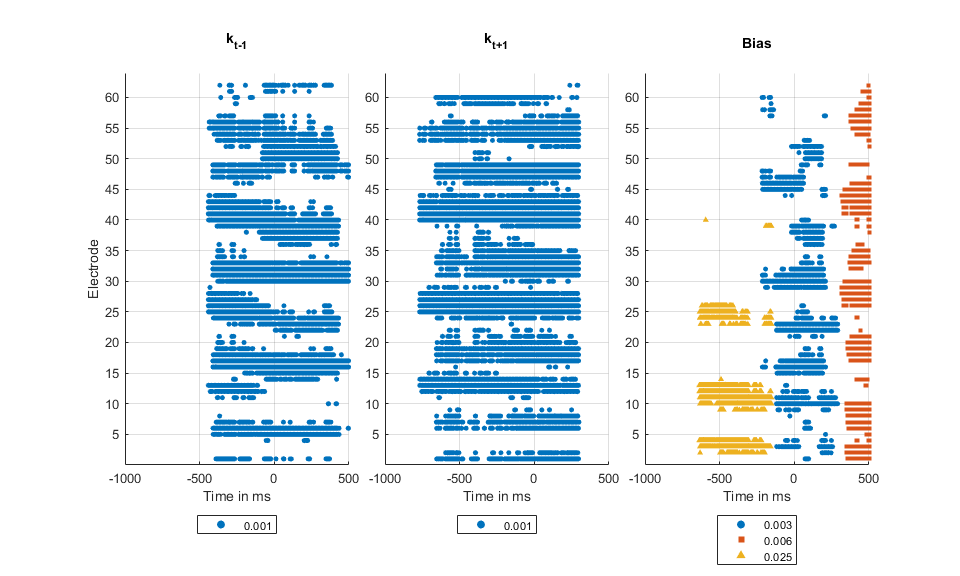

f = figure;
f.Units = 'inches';
f.Position = [ 3.7, 9.3, 10, 6 ];



%sgtitle('Significant clusters for each coefficient.')
tiledlayout(1, 3, 'TileSpacing', 'compact')
clust_shapes = {'o', 's', '^'};

for current_beta = 1:size(mask, 3)
    clusters = unique(mask(:, :, current_beta))';
    clusters(clusters == 0) = []; % Remove 0, 0 is no significant cluster
    
    ax = nexttile;
    title({"", sprintf("%s", betas_names{current_beta}), ""});
    
    if (current_beta) == 1
        ylabel("Electrode");
    end
    
    hold on;
    xlim([-1000, 500]);
    xlabel("Time in ms");
    
    ylim([0, size(mask, 1)]);
    
    this_beta_cluster_ps = {};
    pupu = [];
    
    for current_cluster = clusters
        cluster_indices = squeeze(mask(:, :, current_beta)) == current_cluster;
        [cluster_pos_x, cluster_pos_y] = find(cluster_indices');
        
        t_vals = squeeze(one_sample(:, :, 4, 1));
        t_vals = t_vals(cluster_indices);
        t_vals_stretched = normalize(t_vals, 'range', [-max(abs(t_vals)), max(abs(t_vals))]);
        
        t_vals_norm = round(normalize(t_vals_stretched,'range',[1 256]));
        
        t_vals_stretched = smoothdata(t_vals_stretched, 1, 'movmean', 1000); 
        
        cmap = jet(256);
        
        t_vals_col = zeros(size(t_vals_norm, 1), 3);
        for ii = 1:size(t_vals_norm, 1)
            t_vals_col(ii, :) = cmap(t_vals_norm(ii), :);
        end
        
        
        
        hold on;
        scatter(cluster_pos_x + (epoch_size(1) * 1000), ...
            cluster_pos_y, ...
            15, ...
            clust_shapes{current_cluster}, ...
            'filled');
        
        this_cluster_p = squeeze(cluster_p(:, :, current_beta));
        this_beta_cluster_ps{current_cluster} = string(max(this_cluster_p(cluster_indices)));
        
        
    end
    
    %xline(0);
    ax.YTick = [5:5:60];
    ax.YGrid = 'on';
    ax.XGrid = 'on';
    %yticks([1 5:5:60 64]);
    
    tick_labels = linspace(min(t_vals_stretched), max(t_vals_stretched), 5);
    tick_labels = arrayfun(@(x) sprintf("%0.2f", x), tick_labels);
    
    %colorbar(ax, 'Location', 'southoutside', 'Ticks', normalize(linspace(min(t_vals_stretched), max(t_vals_stretched), 5), 'range', [0, 1]), 'TickLabels', tick_labels);
    %colormap jet;
    
    l = legend(this_beta_cluster_ps, 'location', 'southoutside');
    
    
end

save_svg(f, fullfile("Figures", "significant_clusters"));

## T-value table

Table that shows the 95th and 5th percentile of the t value

t_values = struct();

row_i = 1;

for current_beta = 1:size(mask, 3)
    clusters = unique(mask(:, :, current_beta))';
    clusters(clusters == 0) = [];
    
    for cluster = clusters
        t_values(row_i).beta = betas_names{current_beta};
        t_values(row_i).cluster = cluster;
        
        t_vals_beta = squeeze(one_sample(:, :, 4, current_beta));
        betas_masked = squeeze(mask(:, :, current_beta) == cluster);
        
        t_vals_masked = t_vals_beta(betas_masked);
        
        betas_masked = find(betas_masked);
        
        
        t_values(row_i).top = prctile(t_vals_masked, 90);
        t_values(row_i).bottom = prctile(t_vals_masked, 10);
        
        % Degrees of freedom
        t_values(row_i).df = max(reshape(squeeze(one_sample(:, :, 3, current_beta)), 1, []));
        
        % p Values
        cluster_indices = squeeze(mask(:, :, current_beta)) == cluster;
        this_cluster_p = squeeze(cluster_p(:, :, current_beta));
        t_values(row_i).p = max(this_cluster_p(cluster_indices));
        
        
        
        row_i = row_i + 1;
    end    
end

t_values_table = struct2table(t_values);
t_values_table.Properties.VariableNames = {'Beta', ...
    'Cluster', ...
    '90th percentile time', ...
    '10th percentile', ...
    'df', ...
    'p'};

disp(t_values_table);

       Beta        Cluster    90th percentile time    10th percentile    df      p  
    ___________    _______    ____________________    _______________    __    _____

    {'k_{t-1}'}       1              3.7411               -4.4895        18    0.001
    {'k_{t+1}'}       1              4.0247               -4.2103        18    0.001
    {'Bias'   }       1              3.7217               -3.4765        18    0.003
    {'Bias'   }       2               4.433               -3.6323        18    0.006
    {'Bias'   }       3              3.9449                2.2587        18    0.025




table2latex(t_values_table, './t_value_table.tex');

### EFG Plots

Topoplot of thresholded t-values (according to significant clusters)

Local function

function latencies = iti2latency(itis, varargin)
    p = inputParser;
    addRequired(p, 'itis');
    addOptional(p, 'offset', 0);
    parse(p, itis, varargin{:});
    
    offset = p.Results.offset;
    
    latencies = zeros(length(itis), 1);
    latencies(1) = offset;
    
    for i = 2:length(itis)
        latencies(i) = latencies(i - 1) + itis(i - 1);
    end
end

function f = set_figure_fonts(f, figure_font)
    set(f,'defaultUicontrolFontName', figure_font);
    set(f,'defaultUitableFontName', figure_font);
    set(f,'defaultTextFontName', figure_font);
    set(f,'defaultAxesFontName', figure_font);
    set(f,'defaultUipanelFontName', figure_font);
end

function save_svg(f, filepath)
    % Save figure as svg file and replace all fonts with Arial
    saveas(f, filepath, 'svg');
    
    fid = fopen(sprintf('%s.svg', filepath), 'r');
    svg_file = fread(fid,'*char')';
    fclose(fid);
    
    svg_file = strrep(svg_file, 'Dialog', 'Arial');
    
    fid = fopen(sprintf('%s.svg', filepath),'w');
    fprintf(fid,'%s',svg_file);
    fclose(fid);
end

function color = hex2color(hex_string)
    str = '';
    
    if strcmp(hex_string(1), '#')
        str = hex_string(2:end);
    else
        str = hex_string;
    end
    
    color = sscanf(str, '%2x%2x%2x', [1 3]) / 255;
end